% Repackage NN model.
clc; clear all; close all;
NormalNN.createNN();
clc; clear all;
load('NN Model Library.mat');

% Import cell architecture library with all parameters and models.
clc; clear all; close all;
CellArchLib.createLib();

Unit Cell Architecture Library created successfully.


% Check cell architecture library with all parameters and models.
clc; clear all; close all;
load('Unit Cell Architecture.mat');
cellArchLib.disp();

CellArchLib containing:
S/N:		1
Name:		SC
Cell Type:	Strut
# Nodes:	1
# Struts:	3
Max Degree:	6
Min Degree:	6
c2s Factor:	1.00000

S/N:		2
Name:		BCC
Cell Type:	Strut
# Nodes:	2
# Struts:	8
Max Degree:	8
Min Degree:	8
c2s Factor:	0.86603

S/N:		3
Name:		FCC
Cell Type:	Strut
# Nodes:	4
# Struts:	12
Max Degree:	12
Min Degree:	4
c2s Factor:	0.70711

S/N:		4
Name:		BCC+FCC
Cell Type:	Strut
# Nodes:	5
# Struts:	20
Max Degree:	20
Min Degree:	4
c2s Factor:	0.74684

S/N:		5
Name:		Octet
Cell Type:	Strut
# Nodes:	4
# Struts:	24
Max Degree:	12
Min Degree:	12
c2s Factor:	0.70711

S/N:		6
Name:		Kelvin Cell
Cell Type:	Strut
# Nodes:	12
# Struts:	24
Max Degree:	4
Min Degree:	4
c2s Factor:	0.35355

S/N:		7
Name:		Rhombic Dodecahedron
Cell Type:	Strut
# Nodes:	12
# Struts:	32
Max Degree:	8
Min Degree:	4
c2s Factor:	0.43301



% Check methods in CellArchLib
cellArchLib.findCellArch("SC")

ans = S/N:		1
Name:		SC
Cell Type:	Strut
# Nodes:	1
# Struts:	3
Max Degree:	6
Min Degree:	6
c2s Factor:	1.00000


cellArchLib.findCellArch("BCC+FCC")

ans = S/N:		4
Name:		BCC+FCC
Cell Type:	Strut
# Nodes:	5
# Struts:	20
Max Degree:	20
Min Degree:	4
c2s Factor:	0.74684


cellArchLib.findCellArch("Octet")

ans = S/N:		5
Name:		Octet
Cell Type:	Strut
# Nodes:	4
# Struts:	24
Max Degree:	12
Min Degree:	12
c2s Factor:	0.70711


cellArchLib.findCellArch("Rhombic")


ans =

     []



cellArchLib.findCellArch("Rhombic Dodecahedron")

ans = S/N:		7
Name:		Rhombic Dodecahedron
Cell Type:	Strut
# Nodes:	12
# Struts:	32
Max Degree:	8
Min Degree:	4
c2s Factor:	0.43301


clc; clear all; close all;
load('Lattice Data.mat');

% Create UnitCellStrut objects
num_cases = 0;
for idx_cell = 1:length(unit_cell)
	for idx_length = 1:length(cell_length)
		for idx_density = 1:length(rel_density)
			num_cases = num_cases + 1;
			ExptCases{num_cases,:} = ...
                UnitCellStrut(unit_cell(idx_cell),cell_length(idx_length),rel_density(idx_density));
		end
	end
end
save('Experiment Unit Cells.mat','unit_cell','cell_length','rel_density','ExptCases');

clear all; clc;
load('Experiment Unit Cells.mat');
% Check UnitCell objects.
cases = [1 5 12 21 35 48 56 84];
for idx = cases
	disp(ExptCases{idx,:});
end

S/N:		1
Name:		SC
Cell Length:	4.00000
Rel Density:	0.10000
Strut Length:	4.00000
Strut Width:	0.87490

S/N:		1
Name:		SC
Cell Length:	6.00000
Rel Density:	0.10000
Strut Length:	6.00000
Strut Width:	1.31235

S/N:		1
Name:		SC
Cell Length:	8.00000
Rel Density:	0.40000
Strut Length:	8.00000
Strut Width:	3.90653

S/N:		2
Name:		BCC
Cell Length:	8.00000
Rel Density:	0.10000
Strut Length:	6.92820
Strut Width:	1.15074

S/N:		3
Name:		FCC
Cell Length:	8.00000
Rel Density:	0.30000
Strut Length:	5.65685
Strut Width:	1.97118

S/N:		4
Name:		BCC+FCC
Cell Length:	8.00000
Rel Density:	0.40000
Strut Length:	5.97469
Strut Width:	1.73082

S/N:		5
Name:		Octet
Cell Length:	6.00000
Rel Density:	0.40000
Strut Length:	4.24264
Strut Width:	1.23602

S/N:		7
Name:		Rhombic Dodecahedron
Cell Length:	8.00000
Rel Density:	0.40000
Strut Length:	3.46410
Strut Width:	1.83837



clc; clear all; close all;
load('Lattice Data.mat');
section = "Circular";

freq = 100:10:6300;
% Create StrutLattLayer objects
num_cases = 0;
for idx_cell = 1:length(unit_cell)
	for idx_length = 1:length(cell_length)
		for idx_density = 1:length(rel_density)
			num_cases = num_cases + 1;
			labels(:,num_cases) = strcat(unit_cell(idx_cell),sprintf("; L=%dmm; RD=%.1f", ...
				cell_length(idx_length),rel_density(idx_density)));
            part = LattLayerStrut(unit_cell(idx_cell), ...
                cell_length(idx_length),rel_density(idx_density), ...
                section,30,30,24/cell_length(idx_length));
            layer = LattLayer(section,freq);
            layer.insertPart(part,1);
            ExptCases{num_cases,:} = layer;
		end
	end
end
save('Experiment Unit Cell Layers.mat','labels','unit_cell','cell_length','rel_density','ExptCases');

clc; clear all; close all;
load('Experiment Unit Cell Layers.mat');
% Check UnitCell objects.
cases = [3 10 17 24 31 39 45 55 69 81];
for idx = cases
	disp(ExptCases{idx,:});
end

Lattice Layer containing:
Number:		1
Name:		SC
Cell Length:	4.00000
Rel Density:	0.30000
Strut Length:	4.00000
Strut Width:	1.65340
Cross Section:	Circular
# layers:	6


Lattice Layer containing:
Number:		1
Name:		SC
Cell Length:	8.00000
Rel Density:	0.20000
Strut Length:	8.00000
Strut Width:	2.61450
Cross Section:	Circular
# layers:	3


Lattice Layer containing:
Number:		1
Name:		BCC
Cell Length:	6.00000
Rel Density:	0.10000
Strut Length:	5.19615
Strut Width:	0.86305
Cross Section:	Circular
# layers:	4


Lattice Layer containing:
Number:		1
Name:		BCC
Cell Length:	8.00000
Rel Density:	0.40000
Strut Length:	6.92820
Strut Width:	2.56134
Cross Section:	Circular
# layers:	3


Lattice Layer containing:
Number:		1
Name:		FCC
Cell Length:	6.00000
Rel Density:	0.30000
Strut Length:	4.24264
Strut Width:	1.47838
Cross Section:	Circular
# layers:	4


Lattice Layer containing:
Number:		1
Name:		BCC+FCC
Cell Length:	4.00000
Rel Density:	0.30000
Strut Length:	2.98735
Strut Width:	0.73179
Cross Sect

clc; clear all; close all;
load('Experiment Unit Cell Layers.mat');
load('Lattice SAC.mat','freq');
sample = Lattice('Circle',freq(:,1));
insertLayer(sample,ExptCases{10},1);
insertLayer(sample,ExptCases{20},2);
insertLayer(sample,ExptCases{30},3);
sample

sample = Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:		SC
Cell Length:	8.00000
Rel Density:	0.20000
Strut Length:	8.00000
Strut Width:	2.61450
Cross Section:	Circular
# layers:	3



Number:		2
Lattice Layer containing:
Number:		1
Name:		BCC
Cell Length:	6.00000
Rel Density:	0.40000
Strut Length:	5.19615
Strut Width:	1.92101
Cross Section:	Circular
# layers:	4



Number:		3
Lattice Layer containing:
Number:		1
Name:		FCC
Cell Length:	6.00000
Rel Density:	0.20000
Strut Length:	4.24264
Strut Width:	1.16856
Cross Section:	Circular
# layers:	4




sample.t_sample

ans = 72

removeLayer(sample,1);
sample

sample = Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:		BCC
Cell Length:	6.00000
Rel Density:	0.40000
Strut Length:	5.19615
Strut Width:	1.92101
Cross Section:	Circular
# layers:	4



Number:		2
Lattice Layer containing:
Number:		1
Name:		FCC
Cell Length:	6.00000
Rel Density:	0.20000
Strut Length:	4.24264
Strut Width:	1.16856
Cross Section:	Circular
# layers:	4




removeLayer(sample,2);
sample

sample = Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:		BCC
Cell Length:	6.00000
Rel Density:	0.40000
Strut Length:	5.19615
Strut Width:	1.92101
Cross Section:	Circular
# layers:	4




calcTMM(sample);
calcSAC(sample);

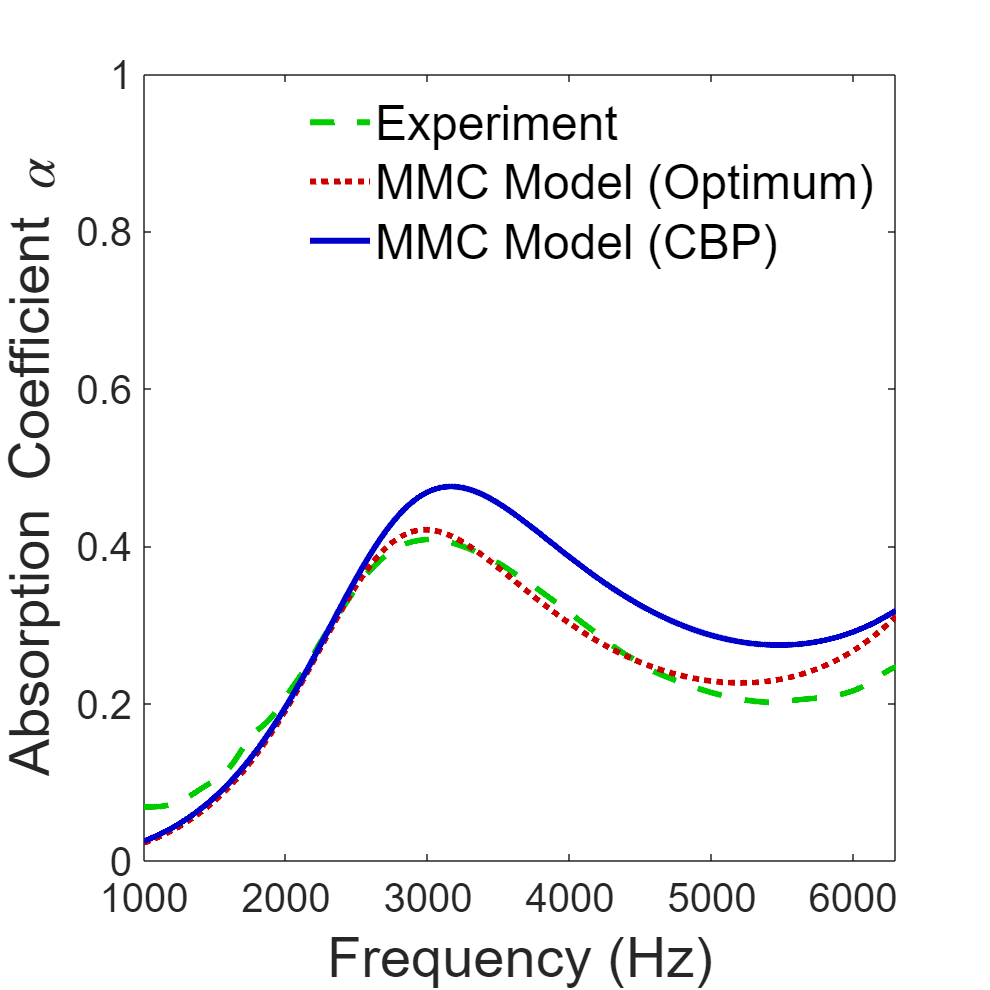

clc; clear all; close all;
load('Lattice SAC.mat');
load('Lattice Data.mat');
load('MMC_errors.mat');
load('Experiment Unit Cell Layers.mat');

figure('Position', [100 100 660 660]);
color = [0 0.8 0;0.8 0 0;0 0 0.8;0.8 0.6 0];
line_style = ["--" ":" "-" "-."];
marker = ['o','+','x','s'];

for idx_case = 1:length(labels)
    f = freq(:,idx_case);
	alpha_expt = SAC_expt(:,idx_case);
	label = labels(idx_case);
	
	plot(freq(:,idx_case),SAC_expt(:,idx_case),'DisplayName','Experiment', ...
		'Color',color(1,:),'LineStyle',line_style(1),'LineWidth',3);
	hold on;
	
	idx_cell = case_idx(idx_case,2);
	idx_length = case_idx(idx_case,3);
	idx_density = case_idx(idx_case,4);
	N_layer = 24/cell_length(idx_length);
	
	% From optimization.
	str_length = strut_length(length(rel_density)*(idx_length-1)+idx_density,idx_cell)*1e-3 * length_corr_best(idx_cell,1);
	str_width = strut_width(length(rel_density)*(idx_length-1)+idx_density,idx_cell)*1e-3 * width_corr_best(idx_cell,1);
	N_layer = 24/cell_length(idx_length);
	delta_1 = delta_1_best(length(rel_density)*(idx_length-1)+idx_density,idx_cell);
	delta_2 = delta_2_best(length(rel_density)*(idx_length-1)+idx_density,idx_cell);
	
	alpha_MMC = MMC_strut(str_length,str_width,N_layer,delta_1,delta_2,f);
	plot(freq(:,idx_case),alpha_MMC,'DisplayName','MMC Model (Optimum)', ...
		'Color',color(2,:),'LineStyle',line_style(2),'LineWidth',3);
	hold on;
	error_MMC_optimum(length(rel_density)*(idx_length-1)+idx_density,idx_cell) = mean(abs(alpha_expt-alpha_MMC));
    
    % From CBP ML Models.
    sample = Lattice('Circle',freq(:,idx_case));
    insertLayer(sample,ExptCases{idx_case},1);
    calcTMM(sample);
    calcSAC(sample);
    plotSAC(sample);
    error_MMC_CBP(length(rel_density)*(idx_length-1)+idx_density,idx_cell) = mean(abs(sample.SAC-alpha_MMC));

    hold on;

    ax = gca;
	ax.FontSize = 20;
	ax.XLim = [1000 6300];
	ax.YLim = [0 1];
	ax.XTick = 1000:1000:6300;
	ax.YTick = 0:0.2:1.0;
	ax.XLabel.String = "Frequency (Hz)";
	ax.YLabel.String = "Absorption Coefficient \alpha";
	ax.XLabel.FontSize = 28;
	ax.YLabel.FontSize = 28;
	legend('Location','northeast','NumColumns',1);
	legend('FontSize',24);
	legend('boxoff');
	
	print(strcat('MMC-',label,'.tif'),'-dtiff','-r500');
	hold off;

    removeLayer(sample,1);
end

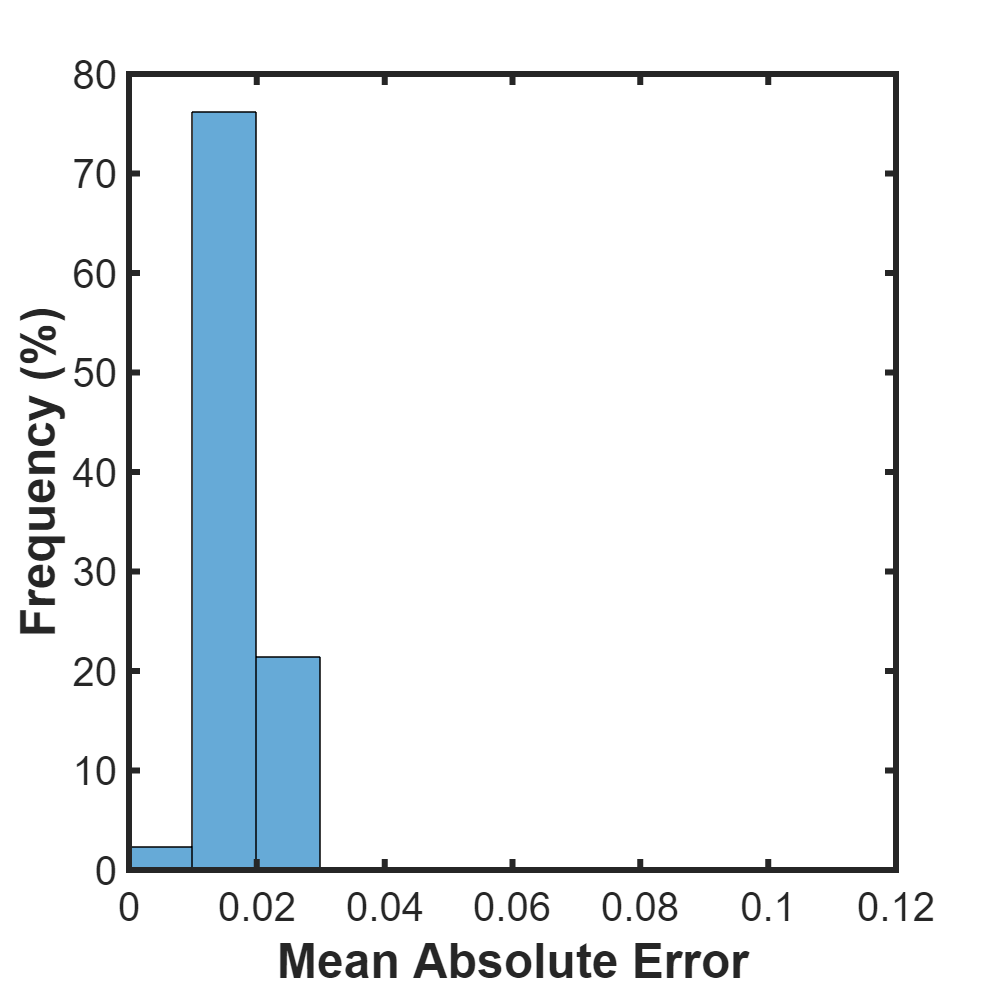

% Plot of Errors
figure('Position', [100 100 660 660]);
x_pdf = [0:1:12]./100;
histogram(reshape(error_MMC_optimum,[],1),x_pdf,'Normalization','pdf');
hold on;

ax = gca;
ax.FontSize = 20;
ax.XLim = [0 12]./100;
ax.XTick = [0:2:12]./100;
ax.YLim = [0 80];
ax.YTick = 0:10:80;
ax.XLabel.String = "Mean Absolute Error";
ax.YLabel.String = "Frequency (%)";
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';
ax.Box = 'on';
ax.LineWidth = 3;

% Saves graph as .png file. Open them up to see.
print("error_MMC_optimum.tif",'-dtiff','-r500');
hold off;

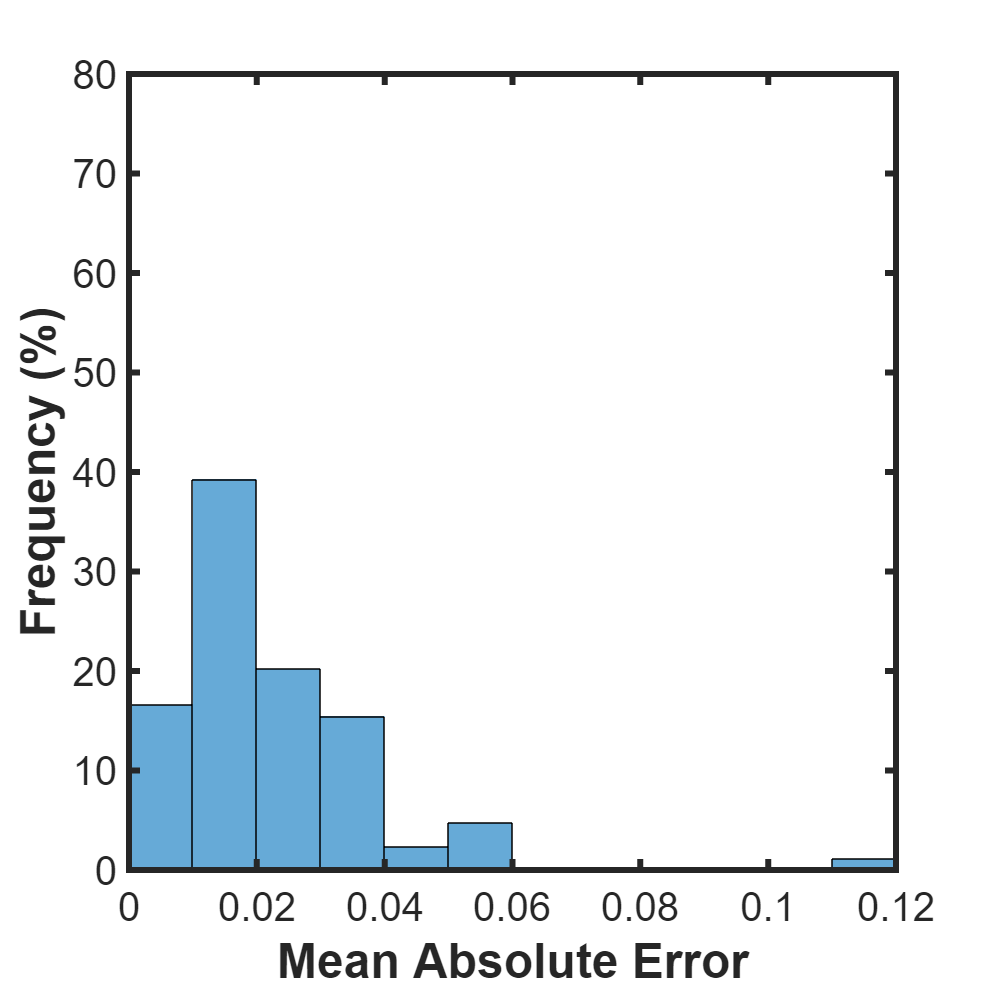


%pause;

figure('Position', [100 100 660 660]);
x_pdf = [0:1:12]./100;
histogram(reshape(error_MMC_CBP,[],1),x_pdf,'Normalization','pdf');
hold on;

ax = gca;
ax.FontSize = 20;
ax.XLim = [0 12]./100;
ax.XTick = [0:2:12]./100;
ax.YLim = [0 80];
ax.YTick = 0:10:80;
ax.XLabel.String = "Mean Absolute Error";
ax.YLabel.String = "Frequency (%)";
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';
ax.Box = 'on';
ax.LineWidth = 3;

% Saves graph as .png file. Open them up to see.
print("error_MMC_CBP.tif",'-dtiff','-r500');
hold off;

% Create LatticeLibrary
clc; clear all; close all;
LatticeLib.createLib();

Lattice Library created successfully.
